data = importdata("data.txt")

data =      1
     5
     7
     9
    11
    15
    17
    19
    23
    23


settings = importdata("settings.txt")

settings =     0.0134
    0.0110



Time = (1 : length(data)) * settings(1)

Time =     0.0134    0.0268    0.0402    0.0536    0.0670    0.0804    0.0938    0.1072    0.1206    0.1340    0.1474    0.1608    0.1742    0.1876    0.2010    0.2144    0.2278    0.2412    0.2546    0.2680    0.2814    0.2948    0.3082    0.3216    0.3350    0.3484    0.3618    0.3752    0.3886    0.4020    0.4154    0.4288    0.4422    0.4556    0.4690    0.4824    0.4958    0.5092    0.5226    0.5360    0.5494    0.5628    0.5762    0.5896    0.6030    0.6164    0.6298    0.6432    0.6566    0.6700


Voltage = data * settings(2)

Voltage =     0.0110
    0.0550
    0.0770
    0.0990
    0.1210
    0.1650
    0.1870
    0.2090
    0.2530
    0.2530



[value, num_max] = max (Voltage(:))

value = 2.7170

num_max = 384

Time_max = Time(num_max)

Time_max = 5.1456

Time_charge = Time_max

Time_charge = 5.1456

Time_discharge = Time(length(Time)) - Time_charge

Time_discharge = 6.8876

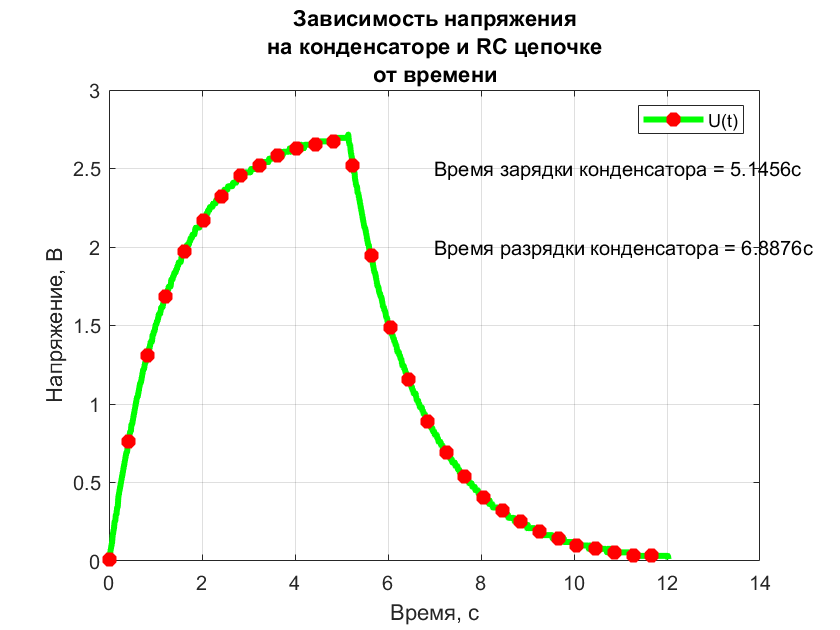


figure('Name', 'Кишишьян Ольга, Б03-008', 'NumberTitle', "off")
plot(Time, Voltage, 'g-*', 'LineWidth', 3, 'MarkerSize', 7, 'MarkerEdgeColor', 'red', 'MarkerIndices', 1:30:length(Time))
grid on
title({'Зависимость напряжения'; 'на конденсаторе и RC цепочке'; 'от времени'})
xlabel('Время, с')
ylabel('Напряжение, В')
legend('U(t)')
text(7, 2.5, ['Время зарядки конденсатора = ' num2str(Time_charge) 'c'])
text(7, 2, ['Время разрядки конденсатора = ' num2str(Time_discharge) 'c'])
set(gcf, 'Visible', 'on')
saveas(gcf, "capacitor.png")
saveas(gcf, "capacitor.svg")